# Data plots

## Init

#### Clear console

clear all
close all
clc

#### Constants

yolo = 1;
osnet = 2;
kalman = 3;

lane = 1;
wild = 2;

newcolors = [ ...
	0 0.4470 0.7410
	0.8500 0.3250 0.0980
	0.9290 0.6940 0.1250
	0.4940 0.1840 0.5560
	0.4660 0.6740 0.1880
	0.3010 0.7450 0.9330
	0.6350 0.0780 0.1840
	];


#### Data init

test.targets = [...
	ones(3,1).*6 % 001, 002, 003
	ones(2,1).*5 % 004, 005
	ones(2,1).*4 % 006, 007
	ones(3,1).*3 % 008, 009, 010
	ones(2,1).*2 % 011, 012
	ones(1,1).*1 % 013
	];

test.count = size(test.targets, 1);

test.level = repmat([yolo osnet kalman], test.count, 1);

test.type = [
	lane % 001
	lane % 002
	wild % 003
	lane % 004
	wild % 005
	lane % 006
	wild % 007
	lane % 008
	wild % 009
	wild % 010
	lane % 011
	lane % 012
	wild % 013
	];

test.time.mean = [...
	0.24004894 , 0.784950874, 0.797297025 % 001 6tl
	0.224269409, 0.739915019, 0.752205395 % 002 6tl
	0.235746472, 0.68770116 , 0.700533593 % 003 6tw
	0.239018379, 0.673827282, 0.6842232   % 004 5tl
	0.237415839, 0.559080984, 0.570291035 % 005 5tw
	0.225169342, 0.567903316, 0.581877666 % 006 4tl
	0.230499342, 0.5294627  , 0.542346695 % 007 4tw
	0.233929591, 0.49146539 , 0.502047739 % 008 3tl
	0.231856908, 0.450159627, 0.461734605 % 009 3tw
	0.21470955 , 0.419129004, 0.432590588 % 010 3tc
	0.219992631, 0.370177939, 0.38181783  % 011 2tl
	0.226351161, 0.418172273, 0.430649857 % 012 2tl
	0.20559609 , 0.292915454, 0.304071426 % 013 1tw
	];
test.time.std =  [...
	0.029728873, 0.104721652, 0.105083633 % 001 6tl
	0.030195605, 0.111580395, 0.111272312 % 002 6tl
	0.035265362, 0.149608963, 0.14852466  % 003 6tw
	0.031765186, 0.098340518, 0.098717626 % 004 5tl
	0.034823993, 0.096515287, 0.098539704 % 005 5tw
	0.028342248, 0.085134289, 0.085715704 % 006 4tl
	0.033203314, 0.092291344, 0.093440082 % 007 4tw
	0.031019932, 0.055343892, 0.055668701 % 008 3tl
	0.027571614, 0.068986891, 0.06970345  % 009 3tw
	0.02554169 , 0.066815221, 0.066043834 % 010 3tc
	0.020351795, 0.054280201, 0.055120297 % 011 2tl
	0.021546285, 0.056856664, 0.058947571 % 012 2tl
	0.016885375, 0.028324395, 0.02810932  % 013 1tw
	];

test.stats.accuracy =    [...
	0.921443736730361, 0.770531400966184 % 001 6tl
	0.911591355599214, 0.831018518518519 % 002 6tl
	0.516666666666667, 0.425531914893617 % 003 6tw
	0.817142857142857, 0.642857142857143 % 004 5tl
	0.552631578947368, 0.477777777777778 % 005 5tw
	0.658653846153846, 0.45              % 006 4tl
	0.508571428571429, 0.4375            % 007 4tw
	0.757894736842105, 0.607843137254902 % 008 3tl
	0.784511784511784, 0.855072463768116 % 009 3tw
	0.880952380952381, 0.846153846153846 % 010 3tc
	0.936            , 1                 % 011 2tl
	0.981132075471698, 0.9765625         % 012 2tl
	1                , 1                 % 013 1tw
	];
test.stats.precision =   [...
	0.912832929782082, 0.770531400966184 % 001 6tl
	0.902097902097902, 0.831018518518519 % 002 6tl
	0.568464730290456, 0.425531914893617 % 003 6tw
	0.776978417266187, 0.642857142857143 % 004 5tl
	0.608974358974359, 0.480446927374302 % 005 5tw
	0.56687898089172 , 0.45              % 006 4tl
	0.548148148148148, 0.4375            % 007 4tw
	0.708609271523179, 0.607843137254902 % 008 3tl
	0.883333333333333, 0.855072463768116 % 009 3tw
	0.980769230769231, 0.846153846153846 % 010 3tc
	1                , 1                 % 011 2tl
	0.992063492063492, 0.9765625         % 012 2tl
	1                , 1                 % 013 1tw
	];
test.stats.recall =      [...
	0.997354497354497, 1                 % 001 6tl
	0.992307692307692, 1                 % 002 6tl
	0.769662921348315, 1                 % 003 6tw
	0.990825688073394, 1                 % 004 5tl
	0.798319327731092, 0.988505747126437 % 005 5tw
	0.967391304347826, 1                 % 006 4tl
	0.747474747474748, 1                 % 007 4tw
	0.981651376146789, 1                 % 008 3tl
	0.854838709677419, 1                 % 009 3tw
	0.88695652173913,  1                 % 010 3tc
	0.933333333333333, 1                 % 011 2tl
	0.984251968503937, 1                 % 012 2tl
	1                , 1                 % 013 1tw
	];
test.stats.specificity = [...
	0.612903225806452, 0                 % 001 6tl
	0.647058823529412, 0                 % 002 6tl
	0.147540983606557, 0                 % 003 6tw
	0.53030303030303 , 0                 % 004 5tl
	0.140845070422535, 0                 % 005 5tw
	0.413793103448276, 0                 % 006 4tl
	0.197368421052632, 0                 % 007 4tw
	0.45679012345679 , 0                 % 008 3tl
	0.428571428571429, 0                 % 009 3tw
	0.818181818181818, 0                 % 010 3tc
	1,                 0                 % 011 2tl
	0.96875          , 0                 % 012 2tl
	1                , 0                 % 013 1tw
	];

test.stats.accuracy = [zeros(test.count,1) test.stats.accuracy];
test.stats.precision = [zeros(test.count,1) test.stats.precision];
test.stats.recall = [zeros(test.count,1) test.stats.recall];
test.stats.specificity = [zeros(test.count,1) test.stats.specificity];

test.stats.detection =   [...
	25.581395348837212 % 001 6tl
	99.27140255009107  % 002 6tl
	86.984126984127    % 003 6tw
	99.32203389830508  % 004 5tl
	88.14814814814814  % 005 5tw
	97.63513513513513  % 006 4tl
	88.72549019607843  % 007 4tw
	99.01960784313725  % 008 3tl
	87.73584905660378  % 009 3tw
	90.9722222222222   % 010 3tc
	94.46308724832215  % 011 2tl
	98.61111111111111  % 012 2tl
	100.0              % 013 1tw
	];

## Plots

### Time performance

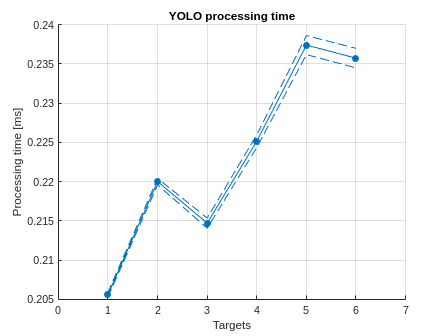

% YOLO time
figure(1);
hold on;
level = yolo;
% ids = filter_id(test, [wild lane], 0:6, [3 5 6 10 11 13], 1);
ids = [13 11 10 6 5 3];
p = plot(test.targets(ids), test.time.mean(ids, level), 'Color', newcolors(level,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(level,:));
plots.yolo.time.mean = p;
p = plot(test.targets(ids), test.time.mean(ids, level) + test.time.std(ids, level).^2, 'Color', newcolors(level,:), 'LineStyle','--');
plots.yolo.time.std.up = p;
p = plot(test.targets(ids), test.time.mean(ids, level) - test.time.std(ids, level).^2, 'Color', newcolors(level,:), 'LineStyle','--');
plots.yolo.time.std.down = p;
grid on;
xlabel('Targets');
ylabel('Processing time [ms]');
xlim([0 7]);

title('YOLO processing time');

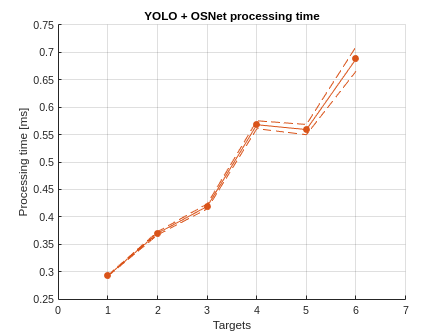


% OSNET time
figure(2);
hold on;
level = osnet;
% ids = filter_id(test, [wild lane], 0:6, [3 5 6 10 11 13], 1);
ids = [13 11 10 6 5 3];
p = plot(test.targets(ids), test.time.mean(ids, level), 'Color', newcolors(level,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(level,:));
plots.osnet.time.mean = p;
p = plot(test.targets(ids), test.time.mean(ids, level) + test.time.std(ids, level).^2, 'Color', newcolors(level,:), 'LineStyle','--');
plots.osnet.time.std.up = p;
p = plot(test.targets(ids), test.time.mean(ids, level) - test.time.std(ids, level).^2, 'Color', newcolors(level,:), 'LineStyle','--');
plots.osnet.time.std.down = p;
grid on;
xlabel('Targets');
ylabel('Processing time [ms]');
xlim([0 7]);

title('YOLO + OSNet processing time');

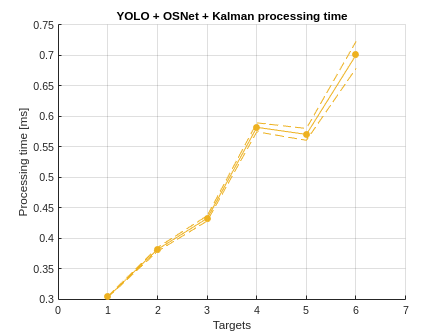



% Kalman time
figure(3);
hold on;
level = kalman;
% ids = filter_id(test, [wild lane], 0:6, [3 5 6 10 11 13], 1);
ids = [13 11 10 6 5 3];
p = plot(test.targets(ids), test.time.mean(ids, level), 'Color', newcolors(level,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(level,:));
plots.kalman.time.mean = p;
p = plot(test.targets(ids), test.time.mean(ids, level) + test.time.std(ids, level).^2, 'Color', newcolors(level,:), 'LineStyle','--');
plots.kalman.time.std.up = p;
p = plot(test.targets(ids), test.time.mean(ids, level) - test.time.std(ids, level).^2, 'Color', newcolors(level,:), 'LineStyle','--');
plots.kalman.time.std.down = p;
grid on;
xlabel('Targets');
ylabel('Processing time [ms]');
xlim([0 7]);

title('YOLO + OSNet + Kalman processing time');

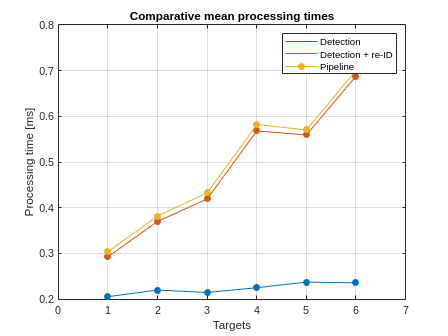


% Combined times
figure(4);
level = yolo;
ids = filter_id(test, [wild lane], 0:6, [3 5 6 10 11 13], 1);
p = plot(test.targets(ids), test.time.mean(ids, level), 'Color', newcolors(level,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(level,:));
hold on;
level = osnet;
ids = filter_id(test, [wild lane], 0:6, [3 5 6 10 11 13], 1);
p = plot(test.targets(ids), test.time.mean(ids, level), 'Color', newcolors(level,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(level,:));
level = kalman;
ids = filter_id(test, [wild lane], 0:6, [3 5 6 10 11 13], 1);
p = plot(test.targets(ids), test.time.mean(ids, level), 'Color', newcolors(level,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(level,:));
grid on;
xlabel('Targets');
ylabel('Processing time [ms]');
xlim([0 7]);
legend({'Detection', 'Detection + re-ID', 'Pipeline'});
title('Comparative mean processing times');

### Accuracy, Precision, Recall, Specificity

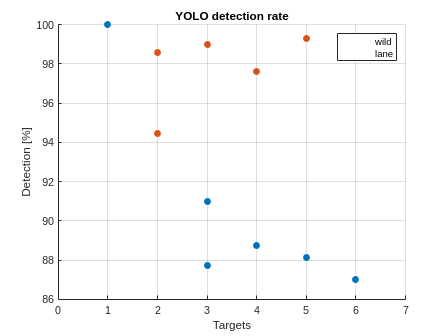

% YOLO detection
figure(5);
clf
level = yolo;
ids = filter_id(test, [wild], 0:6, 2:13, 1);
p = scatter(test.targets(ids), test.stats.detection(ids), 'Color', newcolors(level,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(level,:));
plots.yolo.stats.detection.wild = p;
hold on;
ids = filter_id(test, [lane], 0:6, 2:13, 1);
p = scatter(test.targets(ids), test.stats.detection(ids), 'Color', newcolors(level + 1,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(level + 1,:));
plots.yolo.stats.detection.lane = p;
hold off;
grid on;
xlabel('Targets');
ylabel('Detection [%]');
xlim([0 7]);
legend({'wild', 'lane'});
title('YOLO detection rate');

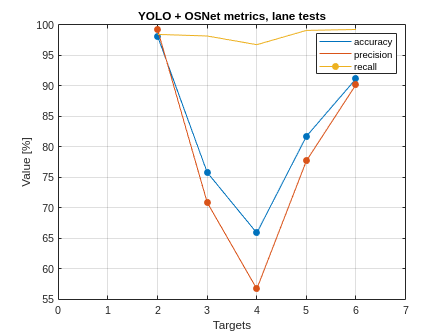


% OSNET lane stats
figure(6);
level = osnet;
ids = filter_id(test, [lane], 0:6, [1 11], 0);
p = plot(test.targets(ids), test.stats.accuracy(ids, level).*100, 'Color', newcolors(1,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(1,:));
plots.osnet.stats.accuracy.lane = p;
hold on;
p = plot(test.targets(ids), test.stats.precision(ids, level).*100, 'Color', newcolors(2,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(2,:));
plots.osnet.stats.precision.lane = p;
p = plot(test.targets(ids), test.stats.recall(ids, level).*100, 'Color', newcolors(3,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(3,:));
plots.osnet.stats.recall.lane = p;
% p = plot(test.targets(ids), test.stats.specificity(ids, level).*100, 'Color', newcolors(4,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(4,:));
% plots.osnet.stats.specificity.lane = p;
grid on;
xlabel('Targets');
ylabel('Value [%]');
xlim([0 7]);
legend({'accuracy', 'precision', 'recall'});
title('YOLO + OSNet metrics, lane tests');

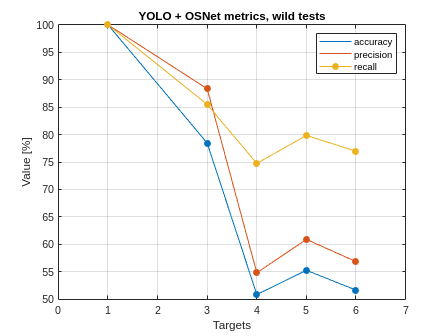


% OSNET wild stats
figure(7);
level = osnet;
ids = filter_id(test, [wild], 0:6, [1 10], 0);
p = plot(test.targets(ids), test.stats.accuracy(ids, level).*100, 'Color', newcolors(1,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(1,:));
plots.osnet.stats.accuracy.lane = p;
hold on;
p = plot(test.targets(ids), test.stats.precision(ids, level).*100, 'Color', newcolors(2,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(2,:));
plots.osnet.stats.precision.lane = p;
p = plot(test.targets(ids), test.stats.recall(ids, level).*100, 'Color', newcolors(3,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(3,:));
plots.osnet.stats.recall.lane = p;
% p = plot(test.targets(ids), test.stats.specificity(ids, level).*100, 'Color', newcolors(4,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(4,:));
% plots.osnet.stats.specificity.lane = p;
grid on;
xlabel('Targets');
ylabel('Value [%]');
xlim([0 7]);
legend({'accuracy', 'precision', 'recall'});
title('YOLO + OSNet metrics, wild tests');

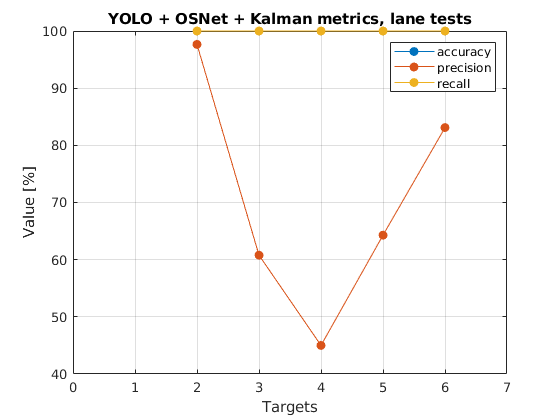


% Kalman lane stats
figure(8);
level = kalman;
ids = filter_id(test, [lane], 0:6, [1 11], 0);
p = plot(test.targets(ids), test.stats.accuracy(ids, level).*100, 'Color', newcolors(1,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(1,:));
plots.kalman.stats.accuracy.lane = p;
hold on;
p = plot(test.targets(ids), test.stats.precision(ids, level).*100, 'Color', newcolors(2,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(2,:));
plots.kalman.stats.precision.lane = p;
p = plot(test.targets(ids), test.stats.recall(ids, level).*100, 'Color', newcolors(3,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(3,:));
plots.kalman.stats.recall.lane = p;
% p = plot(test.targets(ids), test.stats.specificity(ids, level).*100, 'Color', newcolors(4,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(4,:));
% plots.kalman.stats.specificity.lane = p;
grid on;
xlabel('Targets');
ylabel('Value [%]');
xlim([0 7]);
legend({'accuracy', 'precision', 'recall'});
title('YOLO + OSNet + Kalman metrics, lane tests');

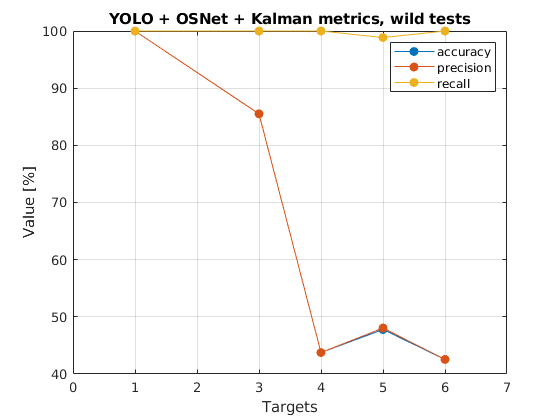


% Kalman wild stats
figure(9);
level = kalman;
ids = filter_id(test, [wild], 0:6, [1 10], 0);
p = plot(test.targets(ids), test.stats.accuracy(ids, level).*100, 'Color', newcolors(1,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(1,:));
plots.kalman.stats.accuracy.lane = p;
hold on;
p = plot(test.targets(ids), test.stats.precision(ids, level).*100, 'Color', newcolors(2,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(2,:));
plots.kalman.stats.precision.lane = p;
p = plot(test.targets(ids), test.stats.recall(ids, level).*100, 'Color', newcolors(3,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(3,:));
plots.kalman.stats.recall.lane = p;
% p = plot(test.targets(ids), test.stats.specificity(ids, level).*100, 'Color', newcolors(4,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(4,:));
% plots.kalman.stats.specificity.lane = p;
grid on;
xlabel('Targets');
ylabel('Value [%]');
xlim([0 7]);
legend({'accuracy', 'precision', 'recall'});
title('YOLO + OSNet + Kalman metrics, wild tests');

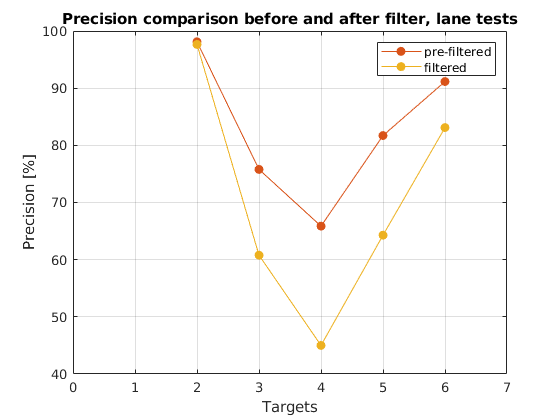

% OSNET & Kalman lane precision
figure(10);
level = osnet;
ids = filter_id(test, [lane], 0:6, [1 11], 0);
p = plot(test.targets(ids), test.stats.accuracy(ids, level).*100, 'Color', newcolors(level,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(level,:));
hold on;
level = kalman;
p = plot(test.targets(ids), test.stats.accuracy(ids, level).*100, 'Color', newcolors(level,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(level,:));
grid on;
xlabel('Targets');
ylabel('Precision [%]');
xlim([0 7]);
legend({'pre-filtered', 'filtered'});
title('Precision comparison before and after filter, lane tests');

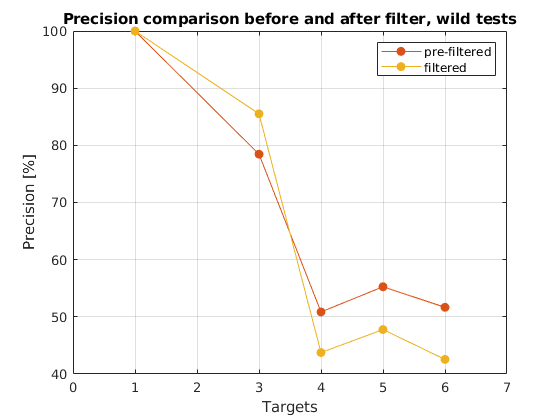

% OSNET & Kalman lane precision
figure(11);
level = osnet;
ids = filter_id(test, [wild], 0:6, [1 10], 0);
p = plot(test.targets(ids), test.stats.accuracy(ids, level).*100, 'Color', newcolors(level,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(level,:));
hold on;
level = kalman;
p = plot(test.targets(ids), test.stats.accuracy(ids, level).*100, 'Color', newcolors(level,:), 'Marker', 'o', 'MarkerFaceColor', newcolors(level,:));
grid on;
xlabel('Targets');
ylabel('Precision [%]');
xlim([0 7]);
legend({'pre-filtered', 'filtered'});
title('Precision comparison before and after filter, wild tests');

## Functions

### Search

#### Filter data

function pick = filter_id(data, type, targets, blacklist, rev)
	pick = [];
	for i = 1:data.count
		if ismember(i,blacklist)
			if rev == 0
				continue
			end
		else
			if rev == 1
				continue
			end 
		end
		if ismember(data.type(i), type) && ismember(data.targets(i), targets)
			pick = [pick i];
		end
	end
end